# Hierarchical Cluster Analysis for Customer Segmentation

dpath = 'customerSegmentationLab.xlsx'; % dataset path
T = readtable(dpath, "Sheet", "Foglio1", 'ReadVariableNames',true, 'ReadRowNames',true);

customers = T.Properties.RowNames; % names of customers
features = T.Properties.VariableNames; % features of customers

head(T); % first few rows of data

                  Age    AnnualIncome    SpendingScore    OnlineVisits    AvgPurchaseValue    DiscountSensitivity
                  ___    ____________    _____________    ____________    ________________    ___________________

    Customer 1    23          28              82               24                38                   79         
    Customer 2    25          32              77               21                42                   74         
    Customer 3    22          26              88               26                35                   81         
    Customer 4    27          35              80               19                46                   69         
    Customer 5    24      

X = table2array(T); % numerical matrix of T
[n, p] = size(X);

% rows represent customers and customers' in columns
fprintf('Rows = %d, Columns = %d', [n, p]);

Rows = 30, Columns = 6

Z = zscore(X); % robust standardization

% euclean distance or dissimilarity matrix
D = pdist(Z, 'euclidean'); % pairwise Euclidean distances

### Linkage Methods and Dendrograms

Hierarchical Clustering using four linkage methods

% linkage structures
LSig = linkage(D, "single");
LCom = linkage(D, "complete");
LAvg = linkage(D, 'average');
LWard = linkage(D, 'ward');

#### Plotting Dendrograms

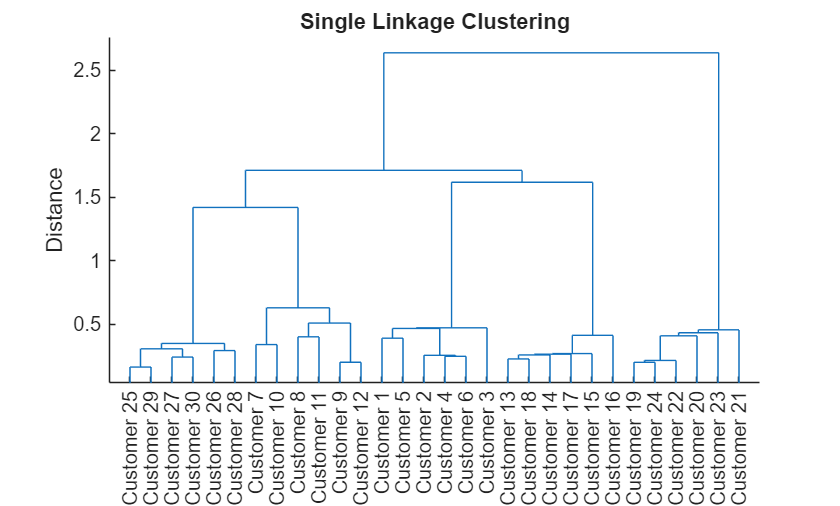

% Create dendrograms to visualize the hierarchical clustering
figure('Name', 'Single Linkage');
dendrogram(LSig, 0, "Labels", customers);
title('Single Linkage Clustering');
ylabel('Distance');

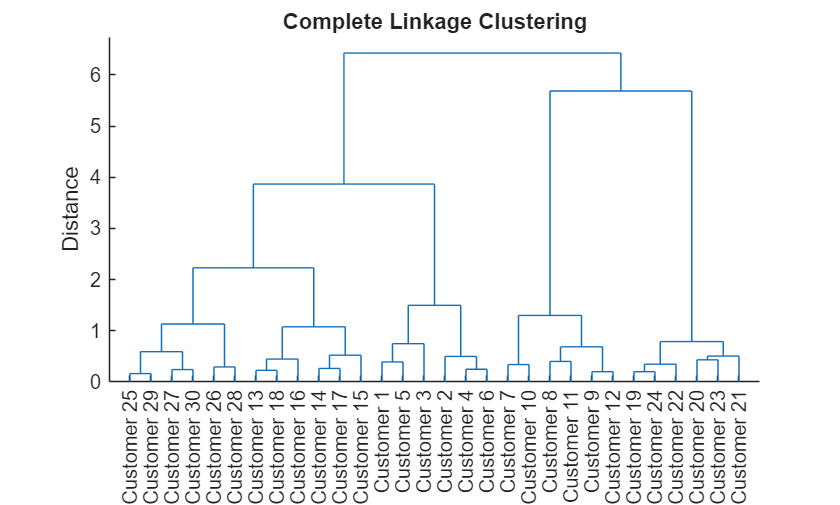

figure('Name', 'Complete Linkage');
dendrogram(LCom, 0, "Labels", customers);
title('Complete Linkage Clustering');
ylabel('Distance');

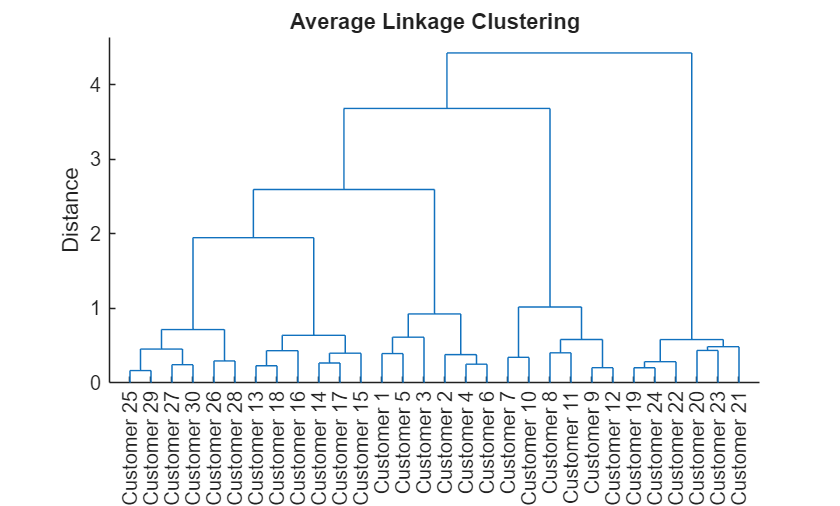

figure('Name', 'Average Linkage');
dendrogram(LAvg, 0, "Labels", customers);
title('Average Linkage Clustering');
ylabel('Distance');

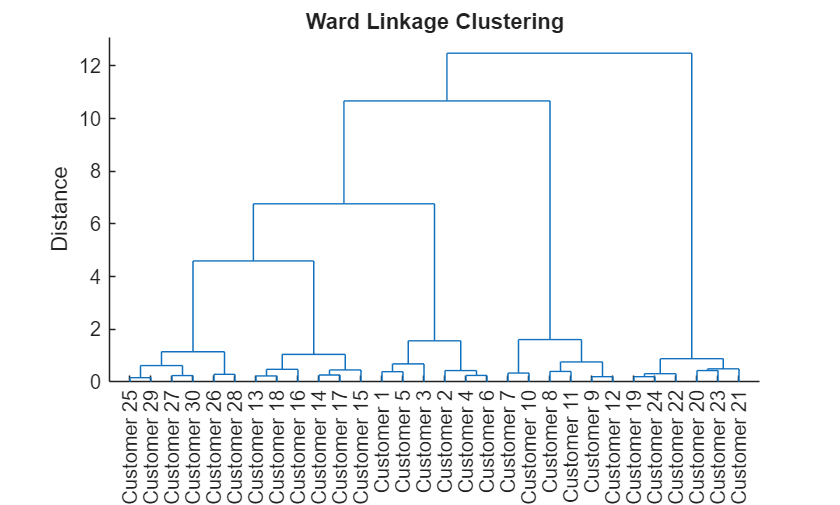

figure('Name', 'Ward Linkage');
dendrogram(LWard, 0, "Labels", customers);
title('Ward Linkage Clustering');
ylabel('Distance');

#### Ward Linkage and Hierarchical Clustering

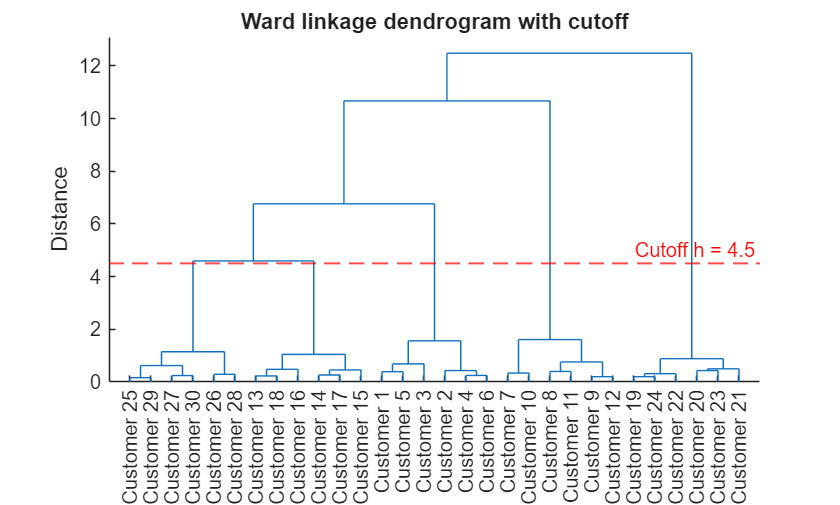

cuttOff = 4.5; % cutt-off value (distance threshold)

figure('Name','Ward dendrogram with cutoff');
dendrogram(LWard, 0, "Labels", customers);
title("Ward linkage dendrogram with cutoff");
ylabel("Distance");
yline(cuttOff, 'r--', sprintf('Cutoff h = %.1f', cuttOff), 'LineWidth', 1);

Extract clusters using the cut-off height

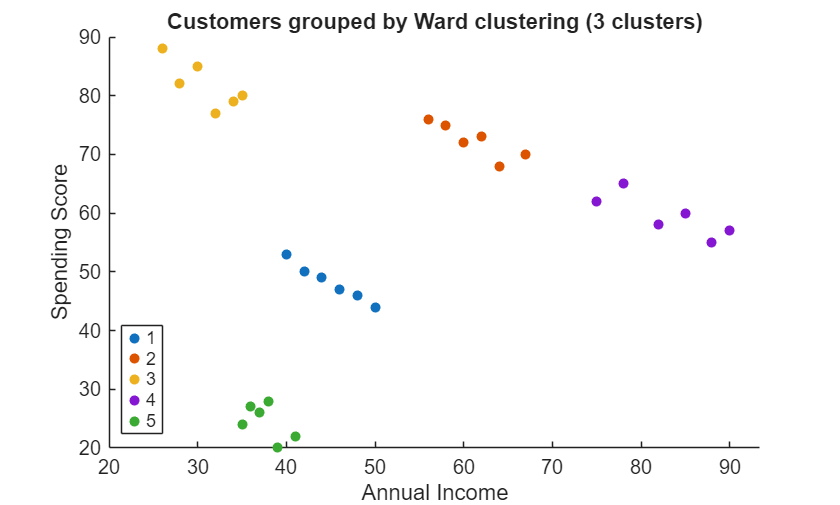

clus = cluster(LWard, "criterion", "distance", "cutoff",cuttOff); % make partitions with a cutt-off
c5Ward = cluster(LWard, "maxclust", 5);

% scatter plot of customers' Annual Income and Spending Score
gscatter(T.AnnualIncome, T.SpendingScore, c5Ward);
xlabel('Annual Income');
ylabel('Spending Score');
title("Customers grouped by Ward clustering (3 clusters)");